# GPR ML model

Note that if we use GPML toolbox, please run the startup file from " E:\ENG\Graduate studies course\gpml-matlab-v4.2-2018-06-11\gpml-matlab-v4.2-2018-06-11" first

## Linear PD + GPR initialization

%% linear GPR+PD+FBL define
q_GPFSF = zeros(6,N); % x y psi u v r
tao_GPFSF = zeros(3,N);
f_GPFSF = zeros(2,N);
q_GPFSF(1:3,1) = [0.5 1 pi/6]';% Set up initial conditions
q_dot_GPFSF = zeros(6,N);
err_GPFSF = zeros(6,N);
new_a_n = zeros(3,N);
new_a_b = zeros(3,N);
new_a_b_new = zeros(3,N);

%% Estimator part initialization
q_hat_GPFSF = zeros(6,N);
aa = [0.3 -0.3 0.1 0.1 0.1 0.1]; 
P_hat_GPFSF = zeros(6,6,N); % Define covariance matrix
P_hat_GPFSF(:,:,1) = P_guess;
q_hat_GPFSF(:,1) = q_guess + transpose(aa); % set the initial guess for estimator
u_m_GPFSF = zeros(3,N);
z_m_GPFSF = zeros(6,N);

### GP+ID parameters initialization

%% GPR variables define
a_GPFSF = zeros(9,N); % [q;qdot;a_b]; 
g_function_GPFSF = zeros(3,N);
sigma_noise = 0.002; % noise variance
dX_PD = size(a_GPFSF,1);
dY_PD = size(g_function_GPFSF,1);

meanfun1_GPFSF = [];
covfun1_GPFSF = @covSEiso;
likfun1_GPFSF = @likGauss;
meanfun2_GPFSF = [];
covfun2_GPFSF = @covSEiso;
likfun2_GPFSF = @likGauss;
meanfun3_GPFSF = [];
covfun3_GPFSF = @covSEiso;
likfun3_GPFSF = @likGauss;

hyp1_GPFSF = struct('mean',[],'cov',[1;1], 'lik', -1);
hyp2_GPFSF = struct('mean',[],'cov',[1;1], 'lik', -1);
hyp3_GPFSF = struct('mean',[],'cov',[1;1], 'lik', -1);
hyp1_min_GPFSF = hyp1_GPFSF;
hyp2_min_GPFSF = hyp2_GPFSF;
hyp3_min_GPFSF = hyp3_GPFSF;

Please note that training and testing dataset matrices: 

Xtrain = zeros(n,dX);

Ytrain = zeros(n,dY);

Xtest = zeros(N-(n+1),dX);

Ytest = zeros(N-n,dY_PD);

## **Linear MPC + GPR Initialization**

%% linear hybrid MPC+GPR define
q_GPMPC = zeros(6,N); % x y psi u v r
tao_GPMPC = zeros(3,N);
f_GPMPC = zeros(2,N);
q_GPMPC(1:3,1) = [0.5 1 pi/6]';% Set up initial conditions
q_dot_GPMPC = zeros(6,N+p);
z_GPMPC = zeros(nr*p,N);
eta_GPMPC = zeros(nc,N+p);
eta_GPMPC_b = zeros(nc,N+p);
tao_head_GPMPC = zeros(nc,N+p);

%% Estimator part initialization
q_hat_GPMPC = zeros(6,N);
P_guess = diag([5 -5 1 1 1 1].^2);  % Set the initial pose covariance estimate as a diagonal matrix
P_hat_GPMPC = zeros(6,6,N); % Define covariance matrix
P_hat_GPMPC(:,:,1) = P_guess;
q_hat_GPMPC(:,1) = q_guess + transpose(aa); % set the initial guess for estimator
u_m_GPMPC = zeros(3,N);
z_m_GPMPC = zeros(6,N);
delta_z_GPMPC = zeros(nr,N);

### GP+MPC parameters initialization

%% GPR variables define
a_GPMPC = zeros(9,N+p); % [q;qdot;a_b]; 
g_function_GPMPC = zeros(6,N+p);
dX_GPMPC = size(a_GPMPC,1);
dY_GPMPC = size(g_function_GPMPC,1);

meanfun_GPMPC = [];    
covfun_GPMPC = @covSEiso;    
likfun_GPMPC = @likGauss;   
hyp_GPMPC = struct('mean',[],'cov',[1;1], 'lik', -1);
hyp_min_GPMPC = hyp_GPMPC;

% meanfun1_GPMPC = [];
% covfun1_GPMPC = @covSEiso;
% likfun1_GPMPC = @likGauss;
% meanfun2_GPMPC = [];
% covfun2_GPMPC = @covSEiso;
% likfun2_GPMPC = @likGauss;
% meanfun3_GPMPC = [];
% covfun3_GPMPC = @covSEiso;
% likfun3_GPMPC = @likGauss;
% 
% hyp1_GPMPC = struct('mean',[],'cov',[1;1], 'lik', -1);
% hyp2_GPMPC = struct('mean',[],'cov',[1;1], 'lik', -1);
% hyp3_GPMPC = struct('mean',[],'cov',[1;1], 'lik', -1);
% hyp1_min_GPMPC = hyp1_GPMPC;
% hyp2_min_GPMPC = hyp2_GPMPC;
% hyp3_min_GPMPC = hyp3_GPMPC;

## Simulate GP+PD training model and control closed-loop system

MaxOber = 20;

%% Update data to the system
for i = 2:N
    [q_dot_GPFSF(1:3,i-1),q_dot_GPFSF(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_GPFSF(4:6,i-1),tao_GPFSF(:,i-1),q_GPFSF(1:3,i-1),t);
    [q_GPFSF(1:3,i),q_GPFSF(4:6,i)]= Vehicle(q_dot_GPFSF(1:3,i-1),q_dot_GPFSF(4:6,i-1),q_GPFSF(1:3,i-1),q_GPFSF(4:6,i-1),t); 
    
     %% Model propriocdeptive sensors with processing noise
    u_m_GPFSF(1,i-1) = tao_GPFSF(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m_GPFSF(2,i-1) = tao_GPFSF(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m_GPFSF(3,i-1) = tao_GPFSF(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m_GPFSF(1,i) = q_GPFSF(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m_GPFSF(2,i) = q_GPFSF(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m_GPFSF(3,i) = q_GPFSF(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m_GPFSF(4,i) = q_GPFSF(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m_GPFSF(5,i) = q_GPFSF(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m_GPFSF(6,i) = q_GPFSF(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_GPFSF(:,i),P_hat_GPFSF(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_GPFSF(:,i-1),u_m_GPFSF(:,i-1),z_m_GPFSF(:,i),R_EKF,Q_EKF,P_hat_GPFSF(:,:,i-1));
    
    err_GPFSF(1,i) = q_hat_GPFSF(1,i-1) - q_d(1,i);
    err_GPFSF(2,i) = q_dot_GPFSF(1,i-1) - q_d_dot(1,i);
    err_GPFSF(3,i) = q_hat_GPFSF(2,i-1) - q_d(2,i);
    err_GPFSF(4,i) = q_dot_GPFSF(2,i-1) - q_d_dot(2,i);
    err_GPFSF(5,i) = q_hat_GPFSF(3,i-1) - q_d(3,i);
    err_GPFSF(6,i) = q_dot_GPFSF(3,i-1) - q_d_dot(3,i);
    new_a_n(:,i) = -K_FSF_MATRIX * err_GPFSF(:,i);
    g_0(1,4) = cos(q_hat_GPFSF(3,i)); 
    g_0(1,5) = -sin(q_hat_GPFSF(3,i)); 
    g_0(2,4) = sin(q_hat_GPFSF(3,i)); 
    g_0(2,5) = cos(q_hat_GPFSF(3,i)); 
    g_0(3,6) = 1;
    g_0(4,4) = -D(1,1)/M(1,1);
    g_0(4,5) = M(2,2)*q_hat_GPFSF(6,i)/M(1,1);
    g_0(5,5) = -D(2,2)/M(2,2);
    g_0(5,6) = M(1,1) * q_hat_GPFSF(4,i)/M(2,2);
    g_0(6,4) = (M(1,1)-M(2,2)) * q_hat_GPFSF(5,i) / M(3,3);
    g_0(6,6) = -D(3,3) / M(3,3);
    Coriolis_GPFSF = [0 0 -M(2,2)*q_hat_GPFSF(5,i);
                      0 0 M(1,1)*q_hat_GPFSF(4,i);
                      M(2,2)*q_hat_GPFSF(5,i) -M(1,1)*q_hat_GPFSF(4,i) 0];
    J_dot = [-q_hat_GPFSF(6,i)*sin(q_hat_GPFSF(3,i)) -q_hat_GPFSF(6,i)*cos(q_hat_GPFSF(3,i)) 0;
            q_hat_GPFSF(6,i)*cos(q_hat_GPFSF(3,i)) -q_hat_GPFSF(6,i)*sin(q_hat_GPFSF(3,i)) 0;
            0 0 0];     
   new_a_b(:,i) = g_0(1:3,4:6) \ (new_a_n(:,i) - J_dot * q_hat_GPFSF(4:6,i)); % PD control acceleration
    %% GP training   

Using GP_Training function to train the sample data and predict the output response, followed by updating the data to the system 

    g_function_GPFSF(:,i-1) = q_dot_GPFSF(4:6,i-1) - new_a_b_new(:,i-1) + sigma_noise*randn(3,1); % Ydataset
    a_GPFSF(:,i) = [err_GPFSF(:,i);new_a_b(:,i)]; % Xdataset(Train + Test) 
    if i > MaxOber
        n = i - MaxOber;
        [~, ~, g_function_GPFSF(1,i), ~] = gp(hyp1_min_GPFSF,@infGaussLik,meanfun1_GPFSF,covfun1_GPFSF,likfun1_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(1,n:i-1)',a_GPFSF(:,i)');
        [~, ~, g_function_GPFSF(2,i), ~] = gp(hyp2_min_GPFSF,@infGaussLik,meanfun2_GPFSF,covfun2_GPFSF,likfun2_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(2,n:i-1)',a_GPFSF(:,i)');
        [~, ~, g_function_GPFSF(3,i), ~] = gp(hyp3_min_GPFSF,@infGaussLik,meanfun3_GPFSF,covfun3_GPFSF,likfun3_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(3,n:i-1)',a_GPFSF(:,i)');
    else
         n = min(i,MaxOber);
        [~, ~, g_function_GPFSF(1,n), ~] = gp(hyp1_min_GPFSF,@infGaussLik,meanfun1_GPFSF,covfun1_GPFSF,likfun1_GPFSF,a_GPFSF(:,1:n-1)',g_function_GPFSF(1,1:n-1)',a_GPFSF(:,n)');
        [~, ~, g_function_GPFSF(2,n), ~] = gp(hyp2_min_GPFSF,@infGaussLik,meanfun2_GPFSF,covfun2_GPFSF,likfun2_GPFSF,a_GPFSF(:,1:n-1)',g_function_GPFSF(2,1:n-1)',a_GPFSF(:,n)');
        [~, ~, g_function_GPFSF(3,n), ~] = gp(hyp3_min_GPFSF,@infGaussLik,meanfun3_GPFSF,covfun3_GPFSF,likfun3_GPFSF,a_GPFSF(:,1:n-1)',g_function_GPFSF(3,1:n-1)',a_GPFSF(:,n)');
    end
    
    if abs(g_function_GPFSF(1,i)) > 1 
        g_function_GPFSF(1,i) = sign(g_function_GPFSF(1,i)) * 1;
    end      
    if abs(g_function_GPFSF(2,i)) > 1
        g_function_GPFSF(2,i) = sign(g_function_GPFSF(2,i)) * 1;
    end
    if abs(g_function_GPFSF(3,i)) > 1
        g_function_GPFSF(3,i) = sign(g_function_GPFSF(3,i)) * 1;
    end
    
    if mod(i,MaxOber) == 0 && i > MaxOber
        hyp1_min_GPFSF = minimize(hyp1_GPFSF,@gp,-5,@infGaussLik,meanfun1_GPFSF,covfun1_GPFSF,likfun1_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(1,n:i-1)');
        hyp2_min_GPFSF = minimize(hyp2_GPFSF,@gp,-5,@infGaussLik,meanfun2_GPFSF,covfun2_GPFSF,likfun2_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(2,n:i-1)');
        hyp3_min_GPFSF = minimize(hyp3_GPFSF,@gp,-5,@infGaussLik,meanfun3_GPFSF,covfun3_GPFSF,likfun3_GPFSF,a_GPFSF(:,n:i-1)',g_function_GPFSF(3,n:i-1)');
    elseif mod(i,MaxOber) == 0 && i <= MaxOber
        hyp1_min_GPFSF = minimize(hyp1_GPFSF,@gp,-5,@infGaussLik,meanfun1_GPFSF,covfun1_GPFSF,likfun1_GPFSF,a_GPFSF(:,1:i-1)',g_function_GPFSF(1,1:i-1)');
        hyp2_min_GPFSF = minimize(hyp2_GPFSF,@gp,-5,@infGaussLik,meanfun2_GPFSF,covfun2_GPFSF,likfun2_GPFSF,a_GPFSF(:,1:i-1)',g_function_GPFSF(2,1:i-1)');
        hyp3_min_GPFSF = minimize(hyp3_GPFSF,@gp,-5,@infGaussLik,meanfun3_GPFSF,covfun3_GPFSF,likfun3_GPFSF,a_GPFSF(:,1:i-1)',g_function_GPFSF(3,1:i-1)');
    end
    
    %% GP training

    new_a_b_new(:,i) =  new_a_b(:,i) - g_function_GPFSF(:,i); 
    tao_GPFSF(:,i) = M * new_a_b_new(:,i) + Coriolis_GPFSF * q_GPFSF(4:6,i) + D * q_GPFSF(4:6,i);
    f_GPFSF(1,i) = tao_GPFSF(1,i)*0.5 + tao_GPFSF(3,i)/B;
    f_GPFSF(2,i) = tao_GPFSF(1,i)*0.5 - tao_GPFSF(3,i)/B;
    
    %% Saturation the force
    %[tao_GPFSF(1,i),tao_GPFSF(3,i)] = sat(tao_GPFSF(1,i),tao_GPFSF(3,i));
    
    %% Simulate disturbances    
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPFSF(:,i), Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPFSF(:,i), Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPFSF(:,i), Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_GPFSF(4:6,i),q_GPFSF(3,i),rho_air,L);
    %tao_GPFSF(:,i) = tao_GPFSF(:,i) -tao_wind(:,i) - tao_wave(:,i);    
end

Function evaluation      0;  Value 5.568417e+00


Function evaluation      0;  Value 5.568453e+00


Function evaluation      0;  Value 5.568530e+00


Function evaluation      0;  Value 2.317818e+00


Function evaluation      0;  Value 2.317795e+00


Function evaluation      0;  Value 2.317794e+00


Function evaluation      0;  Value 2.204821e+00


Function evaluation      0;  Value 2.204933e+00


Function evaluation      0;  Value 2.204938e+00


Function evaluation      0;  Value 2.104342e+00


Function evaluation      0;  Value 2.104244e+00


Function evaluation      0;  Value 2.104298e+00


Function evaluation      0;  Value 2.027661e+00


Function evaluation      0;  Value 2.027655e+00


Function evaluation      0;  Value 2.027606e+00


Function evaluation      0;  Value 1.953527e+00


Function evaluation      0;  Value 1.953638e+00


Function evaluation      0;  Value 1.953481e+00


Function evaluation      0;  Value 1.912931e+00


Function evaluation      0;  Value 1.913005e+00


Function evaluation      0;  Value 1.913103e+00


Function evaluation      0;  Value 1.940881e+00


Function evaluation      0;  Value 1.940854e+00


Function evaluation      0;  Value 1.940946e+00


Function evaluation      0;  Value 1.915512e+00


Function evaluation      0;  Value 1.915651e+00


Function evaluation      0;  Value 1.915644e+00


Function evaluation      0;  Value 1.902256e+00


Function evaluation      0;  Value 1.902316e+00


Function evaluation      0;  Value 1.902253e+00


Function evaluation      0;  Value 1.894375e+00


Function evaluation      0;  Value 1.894407e+00


Function evaluation      0;  Value 1.894413e+00


Function evaluation      0;  Value 1.894373e+00


Function evaluation      0;  Value 1.894356e+00


Function evaluation      0;  Value 1.894624e+00


Function evaluation      0;  Value 1.894657e+00


Function evaluation      0;  Value 1.894310e+00


Function evaluation      0;  Value 1.894323e+00


Function evaluation      0;  Value 1.898728e+00


Function evaluation      0;  Value 1.898651e+00


Function evaluation      0;  Value 1.898732e+00


Function evaluation      0;  Value 1.893111e+00


Function evaluation      0;  Value 1.893187e+00


Function evaluation      0;  Value 1.893179e+00


Function evaluation      0;  Value 1.890241e+00


Function evaluation      0;  Value 1.890400e+00


Function evaluation      0;  Value 1.890195e+00


Function evaluation      0;  Value 1.894058e+00


Function evaluation      0;  Value 1.894015e+00


Function evaluation      0;  Value 1.894096e+00


Function evaluation      0;  Value 1.892673e+00


Function evaluation      0;  Value 1.892637e+00


Function evaluation      0;  Value 1.892718e+00


Function evaluation      0;  Value 1.891611e+00


Function evaluation      0;  Value 1.891708e+00


Function evaluation      0;  Value 1.891791e+00


Function evaluation      0;  Value 1.896711e+00


Function evaluation      0;  Value 1.896756e+00


Function evaluation      0;  Value 1.896666e+00


Function evaluation      0;  Value 1.885915e+00


Function evaluation      0;  Value 1.885914e+00


Function evaluation      0;  Value 1.885915e+00


Function evaluation      0;  Value 1.891585e+00


Function evaluation      0;  Value 1.891429e+00


Function evaluation      0;  Value 1.891313e+00


Function evaluation      0;  Value 1.882432e+00


Function evaluation      0;  Value 1.882615e+00


Function evaluation      0;  Value 1.882696e+00


Function evaluation      0;  Value 1.882025e+00


Function evaluation      0;  Value 1.882027e+00


Function evaluation      0;  Value 1.881952e+00


Function evaluation      0;  Value 1.888100e+00


Function evaluation      0;  Value 1.887961e+00


Function evaluation      0;  Value 1.887996e+00


Function evaluation      0;  Value 1.884072e+00


Function evaluation      0;  Value 1.884064e+00


Function evaluation      0;  Value 1.884132e+00


Function evaluation      0;  Value 1.880733e+00


Function evaluation      0;  Value 1.880657e+00


Function evaluation      0;  Value 1.880620e+00


Function evaluation      0;  Value 1.879582e+00


Function evaluation      0;  Value 1.879549e+00


Function evaluation      0;  Value 1.879694e+00


Function evaluation      0;  Value 1.879735e+00


Function evaluation      0;  Value 1.879656e+00


Function evaluation      0;  Value 1.879557e+00


Function evaluation      0;  Value 1.879794e+00


Function evaluation      0;  Value 1.879956e+00


Function evaluation      0;  Value 1.879881e+00


Function evaluation      0;  Value 1.879146e+00


Function evaluation      0;  Value 1.879542e+00


Function evaluation      0;  Value 1.879192e+00


Function evaluation      0;  Value 3.311489e+00


Function evaluation      0;  Value 3.311684e+00


Function evaluation      0;  Value 3.311654e+00


Function evaluation      0;  Value 2.042850e+00


Function evaluation      0;  Value 2.042843e+00


Function evaluation      0;  Value 2.042827e+00


Function evaluation      0;  Value 1.981677e+00


Function evaluation      0;  Value 1.981707e+00


Function evaluation      0;  Value 1.981686e+00


Function evaluation      0;  Value 1.942611e+00


Function evaluation      0;  Value 1.942478e+00


Function evaluation      0;  Value 1.942467e+00


Function evaluation      0;  Value 1.917670e+00


Function evaluation      0;  Value 1.917530e+00


Function evaluation      0;  Value 1.917805e+00


Function evaluation      0;  Value 1.901762e+00


Function evaluation      0;  Value 1.901969e+00


Function evaluation      0;  Value 1.902048e+00


Function evaluation      0;  Value 1.896021e+00


Function evaluation      0;  Value 1.896200e+00


Function evaluation      0;  Value 1.896033e+00


Function evaluation      0;  Value 1.890244e+00


Function evaluation      0;  Value 1.890156e+00


Function evaluation      0;  Value 1.890305e+00


Function evaluation      0;  Value 1.889063e+00


Function evaluation      0;  Value 1.889437e+00


Function evaluation      0;  Value 1.889127e+00


Function evaluation      0;  Value 1.884886e+00


Function evaluation      0;  Value 1.884781e+00


Function evaluation      0;  Value 1.884944e+00


Function evaluation      0;  Value 1.883589e+00


Function evaluation      0;  Value 1.883621e+00


Function evaluation      0;  Value 1.883662e+00


Function evaluation      0;  Value 1.881640e+00


Function evaluation      0;  Value 1.881653e+00


Function evaluation      0;  Value 1.881735e+00


Function evaluation      0;  Value 1.879212e+00


Function evaluation      0;  Value 1.879101e+00


Function evaluation      0;  Value 1.879271e+00


Function evaluation      0;  Value 1.880097e+00


Function evaluation      0;  Value 1.880129e+00


Function evaluation      0;  Value 1.880203e+00


Function evaluation      0;  Value 1.879573e+00


Function evaluation      0;  Value 1.879779e+00


Function evaluation      0;  Value 1.879634e+00


Function evaluation      0;  Value 1.880502e+00


Function evaluation      0;  Value 1.880458e+00


Function evaluation      0;  Value 1.880668e+00


Function evaluation      0;  Value 1.881134e+00


Function evaluation      0;  Value 1.881089e+00


Function evaluation      0;  Value 1.881123e+00


Function evaluation      0;  Value 1.889639e+00


Function evaluation      0;  Value 1.889712e+00


Function evaluation      0;  Value 1.889644e+00


Function evaluation      0;  Value 1.882235e+00


Function evaluation      0;  Value 1.882204e+00


Function evaluation      0;  Value 1.882122e+00


Function evaluation      0;  Value 1.880686e+00


Function evaluation      0;  Value 1.880505e+00


Function evaluation      0;  Value 1.880533e+00


Function evaluation      0;  Value 1.879697e+00


Function evaluation      0;  Value 1.880024e+00


Function evaluation      0;  Value 1.879873e+00


Function evaluation      0;  Value 1.879628e+00


Function evaluation      0;  Value 1.879525e+00


Function evaluation      0;  Value 1.879463e+00


Function evaluation      0;  Value 1.879629e+00


Function evaluation      0;  Value 1.879540e+00


Function evaluation      0;  Value 1.879629e+00


Function evaluation      0;  Value 1.879218e+00


Function evaluation      0;  Value 1.879328e+00


Function evaluation      0;  Value 1.879202e+00


Function evaluation      0;  Value 1.879120e+00


Function evaluation      0;  Value 1.879133e+00


Function evaluation      0;  Value 1.879147e+00


Function evaluation      0;  Value 1.880932e+00


Function evaluation      0;  Value 1.881023e+00


Function evaluation      0;  Value 1.880932e+00


Function evaluation      0;  Value 1.878932e+00


Function evaluation      0;  Value 1.878928e+00


Function evaluation      0;  Value 1.878875e+00


Function evaluation      0;  Value 1.878800e+00


Function evaluation      0;  Value 1.878899e+00


Function evaluation      0;  Value 1.878926e+00


Function evaluation      0;  Value 1.879215e+00


Function evaluation      0;  Value 1.878950e+00


Function evaluation      0;  Value 1.879014e+00


Function evaluation      0;  Value 1.879658e+00


Function evaluation      0;  Value 1.879774e+00


Function evaluation      0;  Value 1.879637e+00


Function evaluation      0;  Value 1.880623e+00


Function evaluation      0;  Value 1.880389e+00


Function evaluation      0;  Value 1.880649e+00


Function evaluation      0;  Value 1.880094e+00


Function evaluation      0;  Value 1.880242e+00


Function evaluation      0;  Value 1.880134e+00


Function evaluation      0;  Value 1.879336e+00


Function evaluation      0;  Value 1.879357e+00


Function evaluation      0;  Value 1.879647e+00


Function evaluation      0;  Value 1.879122e+00


Function evaluation      0;  Value 1.878932e+00


Function evaluation      0;  Value 1.878963e+00


Function evaluation      0;  Value 1.880049e+00


Function evaluation      0;  Value 1.879933e+00


Function evaluation      0;  Value 1.880140e+00


Function evaluation      0;  Value 1.879663e+00


Function evaluation      0;  Value 1.879687e+00


Function evaluation      0;  Value 1.879685e+00


Function evaluation      0;  Value 1.879578e+00


Function evaluation      0;  Value 1.879393e+00


Function evaluation      0;  Value 1.879553e+00


Function evaluation      0;  Value 1.879040e+00


Function evaluation      0;  Value 1.879072e+00


Function evaluation      0;  Value 1.879054e+00


Function evaluation      0;  Value 1.878140e+00


Function evaluation      0;  Value 1.878153e+00


Function evaluation      0;  Value 1.878314e+00


Function evaluation      0;  Value 1.879905e+00


Function evaluation      0;  Value 1.879770e+00


Function evaluation      0;  Value 1.879916e+00


Function evaluation      0;  Value 1.879697e+00


Function evaluation      0;  Value 1.879583e+00


Function evaluation      0;  Value 1.879698e+00


Function evaluation      0;  Value 1.878106e+00


Function evaluation      0;  Value 1.878067e+00


Function evaluation      0;  Value 1.878403e+00


Function evaluation      0;  Value 1.878633e+00


Function evaluation      0;  Value 1.878876e+00


Function evaluation      0;  Value 1.878570e+00


Function evaluation      0;  Value 1.878531e+00


Function evaluation      0;  Value 1.878691e+00


Function evaluation      0;  Value 1.878509e+00


Function evaluation      0;  Value 1.878786e+00


Function evaluation      0;  Value 1.878928e+00


Function evaluation      0;  Value 1.878882e+00


Function evaluation      0;  Value 1.880797e+00


Function evaluation      0;  Value 1.880895e+00


Function evaluation      0;  Value 1.880863e+00


Function evaluation      0;  Value 1.878499e+00


Function evaluation      0;  Value 1.878467e+00


Function evaluation      0;  Value 1.878632e+00


Function evaluation      0;  Value 1.878718e+00


Function evaluation      0;  Value 1.878738e+00


Function evaluation      0;  Value 1.878782e+00


Function evaluation      0;  Value 1.877987e+00


Function evaluation      0;  Value 1.878079e+00


Function evaluation      0;  Value 1.878180e+00


Function evaluation      0;  Value 1.879704e+00


Function evaluation      0;  Value 1.879413e+00


Function evaluation      0;  Value 1.879646e+00


Function evaluation      0;  Value 1.878166e+00


Function evaluation      0;  Value 1.878178e+00


Function evaluation      0;  Value 1.878235e+00


Function evaluation      0;  Value 1.878211e+00


Function evaluation      0;  Value 1.878319e+00


Function evaluation      0;  Value 1.878389e+00


Function evaluation      0;  Value 1.878013e+00


Function evaluation      0;  Value 1.877983e+00


Function evaluation      0;  Value 1.877990e+00


Function evaluation      0;  Value 1.878518e+00


Function evaluation      0;  Value 1.878418e+00


Function evaluation      0;  Value 1.878491e+00


Function evaluation      0;  Value 1.878724e+00


Function evaluation      0;  Value 1.878699e+00


Function evaluation      0;  Value 1.878840e+00


Function evaluation      0;  Value 1.878438e+00


Function evaluation      0;  Value 1.878415e+00


Function evaluation      0;  Value 1.878503e+00


Function evaluation      0;  Value 1.878226e+00


Function evaluation      0;  Value 1.878432e+00


Function evaluation      0;  Value 1.878446e+00


Function evaluation      0;  Value 1.877961e+00


Function evaluation      0;  Value 1.877881e+00


Function evaluation      0;  Value 1.877972e+00


Function evaluation      0;  Value 1.879267e+00


Function evaluation      0;  Value 1.879452e+00


Function evaluation      0;  Value 1.879458e+00


Function evaluation      0;  Value 1.878526e+00


Function evaluation      0;  Value 1.878381e+00


Function evaluation      0;  Value 1.878484e+00


Function evaluation      0;  Value 1.878403e+00


Function evaluation      0;  Value 1.878501e+00


Function evaluation      0;  Value 1.878378e+00


Function evaluation      0;  Value 1.878075e+00


Function evaluation      0;  Value 1.878063e+00


Function evaluation      0;  Value 1.878027e+00


Function evaluation      0;  Value 1.878255e+00


Function evaluation      0;  Value 1.878525e+00


Function evaluation      0;  Value 1.878464e+00


Function evaluation      0;  Value 1.877751e+00


Function evaluation      0;  Value 1.877809e+00


Function evaluation      0;  Value 1.877970e+00


Function evaluation      0;  Value 1.878863e+00


Function evaluation      0;  Value 1.878901e+00


Function evaluation      0;  Value 1.879088e+00


Function evaluation      0;  Value 1.878344e+00


Function evaluation      0;  Value 1.878313e+00


Function evaluation      0;  Value 1.878359e+00


Function evaluation      0;  Value 1.878855e+00


Function evaluation      0;  Value 1.878865e+00


Function evaluation      0;  Value 1.878884e+00


Function evaluation      0;  Value 1.878622e+00


Function evaluation      0;  Value 1.878287e+00


Function evaluation      0;  Value 1.878313e+00


Function evaluation      0;  Value 1.878865e+00


Function evaluation      0;  Value 1.878970e+00


Function evaluation      0;  Value 1.878871e+00


Function evaluation      0;  Value 1.878915e+00


Function evaluation      0;  Value 1.878967e+00


Function evaluation      0;  Value 1.878894e+00


Function evaluation      0;  Value 1.879029e+00


Function evaluation      0;  Value 1.879080e+00


Function evaluation      0;  Value 1.878896e+00


Function evaluation      0;  Value 1.878808e+00


Function evaluation      0;  Value 1.878783e+00


Function evaluation      0;  Value 1.878873e+00


Function evaluation      0;  Value 1.877979e+00


Function evaluation      0;  Value 1.877926e+00


Function evaluation      0;  Value 1.878080e+00


Function evaluation      0;  Value 1.878162e+00


Function evaluation      0;  Value 1.878117e+00


Function evaluation      0;  Value 1.878309e+00


Function evaluation      0;  Value 1.878264e+00


Function evaluation      0;  Value 1.878227e+00


Function evaluation      0;  Value 1.878296e+00


Function evaluation      0;  Value 1.879278e+00


Function evaluation      0;  Value 1.879020e+00


Function evaluation      0;  Value 1.879011e+00


Function evaluation      0;  Value 1.878472e+00


Function evaluation      0;  Value 1.878666e+00


Function evaluation      0;  Value 1.878582e+00


Function evaluation      0;  Value 1.878755e+00


Function evaluation      0;  Value 1.878719e+00


Function evaluation      0;  Value 1.878660e+00


Function evaluation      0;  Value 1.878497e+00


Function evaluation      0;  Value 1.878530e+00


Function evaluation      0;  Value 1.878443e+00


Function evaluation      0;  Value 1.878191e+00


Function evaluation      0;  Value 1.878147e+00


Function evaluation      0;  Value 1.878211e+00


Function evaluation      0;  Value 1.878685e+00


Function evaluation      0;  Value 1.878564e+00


Function evaluation      0;  Value 1.878562e+00


Function evaluation      0;  Value 1.878267e+00


Function evaluation      0;  Value 1.878201e+00


Function evaluation      0;  Value 1.878259e+00


Function evaluation      0;  Value 1.878411e+00


Function evaluation      0;  Value 1.878246e+00


Function evaluation      0;  Value 1.878277e+00


Function evaluation      0;  Value 1.878314e+00


Function evaluation      0;  Value 1.878279e+00


Function evaluation      0;  Value 1.878122e+00


Function evaluation      0;  Value 1.879107e+00


Function evaluation      0;  Value 1.879165e+00


Function evaluation      0;  Value 1.879197e+00


Function evaluation      0;  Value 1.878438e+00


Function evaluation      0;  Value 1.878745e+00


Function evaluation      0;  Value 1.878634e+00


Function evaluation      0;  Value 1.878681e+00


Function evaluation      0;  Value 1.878461e+00


Function evaluation      0;  Value 1.878390e+00


Function evaluation      0;  Value 1.879032e+00


Function evaluation      0;  Value 1.878943e+00


Function evaluation      0;  Value 1.878994e+00


Function evaluation      0;  Value 1.878463e+00


Function evaluation      0;  Value 1.878361e+00


Function evaluation      0;  Value 1.878453e+00


Function evaluation      0;  Value 1.878520e+00


Function evaluation      0;  Value 1.878612e+00


Function evaluation      0;  Value 1.878484e+00


Function evaluation      0;  Value 1.878349e+00


Function evaluation      0;  Value 1.878294e+00


Function evaluation      0;  Value 1.878397e+00


Function evaluation      0;  Value 1.878477e+00


Function evaluation      0;  Value 1.878591e+00


Function evaluation      0;  Value 1.878541e+00


Function evaluation      0;  Value 1.878232e+00


Function evaluation      0;  Value 1.878299e+00


Function evaluation      0;  Value 1.878057e+00


Function evaluation      0;  Value 1.878453e+00


Function evaluation      0;  Value 1.878325e+00


Function evaluation      0;  Value 1.878334e+00


Function evaluation      0;  Value 1.878368e+00


Function evaluation      0;  Value 1.878499e+00


Function evaluation      0;  Value 1.878601e+00


Function evaluation      0;  Value 2.667936e+00


Function evaluation      0;  Value 2.668056e+00


Function evaluation      0;  Value 2.668072e+00


Function evaluation      0;  Value 2.022109e+00


Function evaluation      0;  Value 2.022108e+00


Function evaluation      0;  Value 2.022024e+00


Function evaluation      0;  Value 1.962637e+00


Function evaluation      0;  Value 1.962477e+00


Function evaluation      0;  Value 1.962619e+00


Function evaluation      0;  Value 1.927823e+00


Function evaluation      0;  Value 1.928234e+00


Function evaluation      0;  Value 1.927919e+00


Function evaluation      0;  Value 1.905223e+00


Function evaluation      0;  Value 1.905234e+00


Function evaluation      0;  Value 1.905340e+00


Function evaluation      0;  Value 1.893886e+00


Function evaluation      0;  Value 1.893793e+00


Function evaluation      0;  Value 1.893708e+00


Function evaluation      0;  Value 1.887114e+00


Function evaluation      0;  Value 1.886789e+00


Function evaluation      0;  Value 1.886935e+00


Function evaluation      0;  Value 1.883217e+00


Function evaluation      0;  Value 1.883170e+00


Function evaluation      0;  Value 1.883396e+00


Function evaluation      0;  Value 1.881190e+00


Function evaluation      0;  Value 1.881107e+00


Function evaluation      0;  Value 1.881181e+00


Function evaluation      0;  Value 1.880376e+00


Function evaluation      0;  Value 1.880329e+00


Function evaluation      0;  Value 1.880404e+00


Function evaluation      0;  Value 1.878982e+00


Function evaluation      0;  Value 1.878941e+00


Function evaluation      0;  Value 1.878996e+00


Function evaluation      0;  Value 1.878946e+00


Function evaluation      0;  Value 1.878755e+00


Function evaluation      0;  Value 1.878692e+00


Function evaluation      0;  Value 1.878236e+00


Function evaluation      0;  Value 1.878428e+00


Function evaluation      0;  Value 1.878310e+00


Function evaluation      0;  Value 1.878193e+00


Function evaluation      0;  Value 1.878207e+00


Function evaluation      0;  Value 1.878140e+00


Function evaluation      0;  Value 1.878022e+00


Function evaluation      0;  Value 1.878021e+00


Function evaluation      0;  Value 1.878057e+00


Function evaluation      0;  Value 1.878369e+00


Function evaluation      0;  Value 1.878323e+00


Function evaluation      0;  Value 1.878325e+00


Function evaluation      0;  Value 1.878164e+00


Function evaluation      0;  Value 1.878017e+00


Function evaluation      0;  Value 1.877995e+00


Function evaluation      0;  Value 1.877958e+00


Function evaluation      0;  Value 1.878079e+00


Function evaluation      0;  Value 1.877940e+00


Function evaluation      0;  Value 1.877981e+00


Function evaluation      0;  Value 1.878223e+00


Function evaluation      0;  Value 1.878034e+00


Function evaluation      0;  Value 1.877877e+00


Function evaluation      0;  Value 1.878119e+00


Function evaluation      0;  Value 1.877800e+00


Function evaluation      0;  Value 1.877836e+00


Function evaluation      0;  Value 1.877733e+00


Function evaluation      0;  Value 1.877844e+00


Function evaluation      0;  Value 1.877684e+00


Function evaluation      0;  Value 1.877809e+00


Function evaluation      0;  Value 1.877759e+00


Function evaluation      0;  Value 1.877744e+00


Function evaluation      0;  Value 1.877794e+00


Function evaluation      0;  Value 1.877929e+00


Function evaluation      0;  Value 1.877655e+00


Function evaluation      0;  Value 1.877728e+00


Function evaluation      0;  Value 1.877619e+00


Function evaluation      0;  Value 1.877915e+00


Function evaluation      0;  Value 1.877931e+00


Function evaluation      0;  Value 1.877767e+00


Function evaluation      0;  Value 1.877704e+00


Function evaluation      0;  Value 1.877588e+00


Function evaluation      0;  Value 1.877953e+00


Function evaluation      0;  Value 1.877689e+00


Function evaluation      0;  Value 1.877575e+00


Function evaluation      0;  Value 1.877671e+00


Function evaluation      0;  Value 1.877700e+00


Function evaluation      0;  Value 1.877769e+00


Function evaluation      0;  Value 1.877554e+00


Function evaluation      0;  Value 1.877645e+00


Function evaluation      0;  Value 1.877656e+00


Function evaluation      0;  Value 1.877521e+00


Function evaluation      0;  Value 1.877455e+00


Function evaluation      0;  Value 1.877563e+00


Function evaluation      0;  Value 1.877510e+00


Function evaluation      0;  Value 1.877401e+00


Function evaluation      0;  Value 1.877493e+00


Function evaluation      0;  Value 1.877485e+00


Function evaluation      0;  Value 1.877657e+00


Function evaluation      0;  Value 1.877462e+00


Function evaluation      0;  Value 1.877372e+00


Function evaluation      0;  Value 1.877524e+00


Function evaluation      0;  Value 1.877501e+00


Function evaluation      0;  Value 1.877532e+00


Function evaluation      0;  Value 1.877494e+00


Function evaluation      0;  Value 1.877599e+00


Function evaluation      0;  Value 1.877418e+00


Function evaluation      0;  Value 1.877624e+00


Function evaluation      0;  Value 1.877396e+00


Function evaluation      0;  Value 1.877365e+00


Function evaluation      0;  Value 1.877420e+00


Function evaluation      0;  Value 1.877423e+00


Function evaluation      0;  Value 1.877402e+00


Function evaluation      0;  Value 1.877701e+00


Function evaluation      0;  Value 1.877696e+00


Function evaluation      0;  Value 1.877635e+00


Function evaluation      0;  Value 1.877521e+00


Function evaluation      0;  Value 1.877503e+00


Function evaluation      0;  Value 1.877634e+00


Function evaluation      0;  Value 1.877587e+00


Function evaluation      0;  Value 1.877463e+00


Function evaluation      0;  Value 1.877506e+00


Function evaluation      0;  Value 1.877496e+00


Function evaluation      0;  Value 1.877782e+00


Function evaluation      0;  Value 1.877450e+00


Function evaluation      0;  Value 1.877335e+00


Function evaluation      0;  Value 1.877454e+00


Function evaluation      0;  Value 1.877524e+00


Function evaluation      0;  Value 1.877560e+00


Function evaluation      0;  Value 1.877496e+00


Function evaluation      0;  Value 1.877813e+00


Function evaluation      0;  Value 1.877445e+00


Function evaluation      0;  Value 1.877370e+00


Function evaluation      0;  Value 1.877552e+00


Function evaluation      0;  Value 1.877427e+00


Function evaluation      0;  Value 1.877328e+00


Function evaluation      0;  Value 1.877444e+00


Function evaluation      0;  Value 1.877597e+00


Function evaluation      0;  Value 1.877602e+00


Function evaluation      0;  Value 1.877512e+00


Function evaluation      0;  Value 1.877534e+00


Function evaluation      0;  Value 1.877488e+00


Function evaluation      0;  Value 1.877663e+00


Function evaluation      0;  Value 1.877751e+00


Function evaluation      0;  Value 1.878028e+00


Function evaluation      0;  Value 1.877685e+00


Function evaluation      0;  Value 1.877544e+00


Function evaluation      0;  Value 1.877353e+00


Function evaluation      0;  Value 1.877360e+00


Function evaluation      0;  Value 1.877493e+00


Function evaluation      0;  Value 1.877445e+00


Function evaluation      0;  Value 1.877476e+00


Function evaluation      0;  Value 1.877771e+00


Function evaluation      0;  Value 1.877892e+00


Function evaluation      0;  Value 1.877859e+00


Function evaluation      0;  Value 1.877398e+00


Function evaluation      0;  Value 1.877394e+00


Function evaluation      0;  Value 1.877347e+00


Function evaluation      0;  Value 1.877562e+00


Function evaluation      0;  Value 1.877665e+00


Function evaluation      0;  Value 1.877603e+00


Function evaluation      0;  Value 1.877322e+00


Function evaluation      0;  Value 1.877503e+00


Function evaluation      0;  Value 1.877341e+00


Function evaluation      0;  Value 1.877413e+00


Function evaluation      0;  Value 1.877745e+00


Function evaluation      0;  Value 1.877445e+00


Function evaluation      0;  Value 1.877459e+00


Function evaluation      0;  Value 1.877389e+00


Function evaluation      0;  Value 1.877328e+00


Function evaluation      0;  Value 1.877606e+00


Function evaluation      0;  Value 1.877696e+00


Function evaluation      0;  Value 1.877566e+00


Function evaluation      0;  Value 1.877558e+00


Function evaluation      0;  Value 1.877466e+00


Function evaluation      0;  Value 1.877561e+00


Function evaluation      0;  Value 1.877494e+00


Function evaluation      0;  Value 1.877488e+00


Function evaluation      0;  Value 1.877469e+00


Function evaluation      0;  Value 1.877524e+00


Function evaluation      0;  Value 1.877428e+00


Function evaluation      0;  Value 1.877490e+00


Function evaluation      0;  Value 1.877462e+00


Function evaluation      0;  Value 1.877282e+00


Function evaluation      0;  Value 1.877520e+00


Function evaluation      0;  Value 1.877537e+00


Function evaluation      0;  Value 1.877512e+00


Function evaluation      0;  Value 1.877590e+00


Function evaluation      0;  Value 1.877495e+00


Function evaluation      0;  Value 1.877339e+00


Function evaluation      0;  Value 1.877525e+00


Function evaluation      0;  Value 1.877419e+00


Function evaluation      0;  Value 1.877429e+00


Function evaluation      0;  Value 1.877363e+00


Function evaluation      0;  Value 2.659883e+00


Function evaluation      0;  Value 2.659766e+00


Function evaluation      0;  Value 2.659802e+00


Function evaluation      0;  Value 2.021611e+00


Function evaluation      0;  Value 2.021625e+00


Function evaluation      0;  Value 2.021586e+00


Function evaluation      0;  Value 1.964783e+00


Function evaluation      0;  Value 1.964453e+00


Function evaluation      0;  Value 1.964488e+00


Function evaluation      0;  Value 1.928652e+00


Function evaluation      0;  Value 1.928838e+00


Function evaluation      0;  Value 1.928854e+00


Function evaluation      0;  Value 1.906657e+00


Function evaluation      0;  Value 1.906711e+00


Function evaluation      0;  Value 1.906594e+00


Function evaluation      0;  Value 1.896093e+00


Function evaluation      0;  Value 1.895867e+00


Function evaluation      0;  Value 1.895952e+00


Function evaluation      0;  Value 1.887936e+00


Function evaluation      0;  Value 1.887927e+00


Function evaluation      0;  Value 1.887897e+00


Function evaluation      0;  Value 1.885384e+00


Function evaluation      0;  Value 1.885287e+00


Function evaluation      0;  Value 1.885406e+00


Function evaluation      0;  Value 1.883524e+00


Function evaluation      0;  Value 1.883685e+00


Function evaluation      0;  Value 1.883535e+00


Function evaluation      0;  Value 1.881462e+00


Function evaluation      0;  Value 1.881735e+00


Function evaluation      0;  Value 1.881379e+00


Function evaluation      0;  Value 1.880652e+00


Function evaluation      0;  Value 1.880597e+00


Function evaluation      0;  Value 1.880544e+00


Function evaluation      0;  Value 1.879665e+00


Function evaluation      0;  Value 1.879465e+00


Function evaluation      0;  Value 1.879572e+00


Function evaluation      0;  Value 1.879924e+00


Function evaluation      0;  Value 1.879805e+00


Function evaluation      0;  Value 1.879805e+00


Function evaluation      0;  Value 1.879423e+00


Function evaluation      0;  Value 1.879345e+00


Function evaluation      0;  Value 1.879451e+00


Function evaluation      0;  Value 1.879665e+00


Function evaluation      0;  Value 1.879564e+00


Function evaluation      0;  Value 1.879558e+00


Function evaluation      0;  Value 1.879278e+00


Function evaluation      0;  Value 1.879436e+00


Function evaluation      0;  Value 1.879416e+00


Function evaluation      0;  Value 1.880310e+00


Function evaluation      0;  Value 1.880318e+00


Function evaluation      0;  Value 1.880202e+00


Function evaluation      0;  Value 1.879044e+00


Function evaluation      0;  Value 1.879290e+00


Function evaluation      0;  Value 1.879251e+00


Function evaluation      0;  Value 1.878631e+00


Function evaluation      0;  Value 1.878701e+00


Function evaluation      0;  Value 1.878619e+00


Function evaluation      0;  Value 1.878887e+00


Function evaluation      0;  Value 1.879050e+00


Function evaluation      0;  Value 1.878825e+00


Function evaluation      0;  Value 1.878782e+00


Function evaluation      0;  Value 1.878962e+00


Function evaluation      0;  Value 1.878817e+00


Function evaluation      0;  Value 1.878638e+00


Function evaluation      0;  Value 1.878643e+00


Function evaluation      0;  Value 1.878510e+00


Function evaluation      0;  Value 1.878901e+00


Function evaluation      0;  Value 1.878942e+00


Function evaluation      0;  Value 1.878814e+00


Function evaluation      0;  Value 1.878587e+00


Function evaluation      0;  Value 1.878561e+00


Function evaluation      0;  Value 1.878366e+00


Function evaluation      0;  Value 1.878310e+00


Function evaluation      0;  Value 1.878303e+00


Function evaluation      0;  Value 1.878319e+00


Function evaluation      0;  Value 1.878961e+00


Function evaluation      0;  Value 1.879173e+00


Function evaluation      0;  Value 1.878862e+00


Function evaluation      0;  Value 1.878583e+00


Function evaluation      0;  Value 1.878576e+00


Function evaluation      0;  Value 1.878429e+00


Function evaluation      0;  Value 1.878693e+00


Function evaluation      0;  Value 1.878674e+00


Function evaluation      0;  Value 1.878616e+00


Function evaluation      0;  Value 1.878277e+00


Function evaluation      0;  Value 1.878258e+00


Function evaluation      0;  Value 1.878407e+00


Function evaluation      0;  Value 1.878801e+00


Function evaluation      0;  Value 1.879013e+00


Function evaluation      0;  Value 1.879092e+00


Function evaluation      0;  Value 1.878300e+00


Function evaluation      0;  Value 1.878356e+00


Function evaluation      0;  Value 1.878358e+00


Function evaluation      0;  Value 1.878934e+00


Function evaluation      0;  Value 1.878982e+00


Function evaluation      0;  Value 1.878874e+00


Function evaluation      0;  Value 1.878582e+00


Function evaluation      0;  Value 1.878475e+00


Function evaluation      0;  Value 1.878364e+00


Function evaluation      0;  Value 1.878309e+00


Function evaluation      0;  Value 1.878367e+00


Function evaluation      0;  Value 1.878505e+00


Function evaluation      0;  Value 1.878456e+00


Function evaluation      0;  Value 1.878300e+00


Function evaluation      0;  Value 1.878278e+00


Function evaluation      0;  Value 1.878115e+00


Function evaluation      0;  Value 1.878173e+00


Function evaluation      0;  Value 1.878218e+00


Function evaluation      0;  Value 1.878138e+00


Function evaluation      0;  Value 1.878236e+00


Function evaluation      0;  Value 1.878351e+00


Function evaluation      0;  Value 1.879072e+00


Function evaluation      0;  Value 1.879229e+00


Function evaluation      0;  Value 1.879155e+00


Function evaluation      0;  Value 1.878450e+00


Function evaluation      0;  Value 1.878551e+00


Function evaluation      0;  Value 1.878391e+00


Function evaluation      0;  Value 1.878451e+00


Function evaluation      0;  Value 1.878583e+00


Function evaluation      0;  Value 1.878422e+00


Function evaluation      0;  Value 1.878472e+00


Function evaluation      0;  Value 1.878673e+00


Function evaluation      0;  Value 1.878540e+00


Function evaluation      0;  Value 1.878298e+00


Function evaluation      0;  Value 1.878216e+00


Function evaluation      0;  Value 1.878260e+00


Function evaluation      0;  Value 1.878235e+00


Function evaluation      0;  Value 1.878116e+00


Function evaluation      0;  Value 1.878152e+00


Function evaluation      0;  Value 1.878835e+00


Function evaluation      0;  Value 1.878828e+00


Function evaluation      0;  Value 1.878833e+00


Function evaluation      0;  Value 1.878446e+00


Function evaluation      0;  Value 1.878699e+00


Function evaluation      0;  Value 1.878576e+00


Function evaluation      0;  Value 1.878555e+00


Function evaluation      0;  Value 1.878514e+00


Function evaluation      0;  Value 1.878693e+00


Function evaluation      0;  Value 1.878230e+00


Function evaluation      0;  Value 1.878318e+00


Function evaluation      0;  Value 1.878403e+00


Function evaluation      0;  Value 1.878438e+00


Function evaluation      0;  Value 1.878104e+00


Function evaluation      0;  Value 1.878293e+00


Function evaluation      0;  Value 1.878175e+00


Function evaluation      0;  Value 1.878172e+00


Function evaluation      0;  Value 1.878159e+00


Function evaluation      0;  Value 1.878624e+00


Function evaluation      0;  Value 1.878616e+00


Function evaluation      0;  Value 1.878569e+00


Function evaluation      0;  Value 1.878466e+00


Function evaluation      0;  Value 1.878485e+00


Function evaluation      0;  Value 1.878355e+00


Function evaluation      0;  Value 1.878369e+00


Function evaluation      0;  Value 1.878375e+00


Function evaluation      0;  Value 1.878254e+00


Function evaluation      0;  Value 1.878511e+00


Function evaluation      0;  Value 1.878594e+00


Function evaluation      0;  Value 1.878559e+00


Function evaluation      0;  Value 1.878950e+00


Function evaluation      0;  Value 1.878955e+00


Function evaluation      0;  Value 1.878836e+00


Function evaluation      0;  Value 1.878419e+00


Function evaluation      0;  Value 1.878373e+00


Function evaluation      0;  Value 1.878277e+00


Function evaluation      0;  Value 1.878185e+00


Function evaluation      0;  Value 1.878358e+00


Function evaluation      0;  Value 1.878177e+00


Function evaluation      0;  Value 1.878145e+00


Function evaluation      0;  Value 1.878222e+00


Function evaluation      0;  Value 1.878003e+00


Function evaluation      0;  Value 1.877898e+00


Function evaluation      0;  Value 1.877935e+00


Function evaluation      0;  Value 1.877859e+00


Function evaluation      0;  Value 1.878151e+00


Function evaluation      0;  Value 1.878078e+00


Function evaluation      0;  Value 1.878416e+00


Function evaluation      0;  Value 1.878801e+00


Function evaluation      0;  Value 1.878699e+00


Function evaluation      0;  Value 1.878858e+00


Function evaluation      0;  Value 1.878591e+00


Function evaluation      0;  Value 1.878495e+00


Function evaluation      0;  Value 1.878507e+00


Function evaluation      0;  Value 1.879355e+00


Function evaluation      0;  Value 1.879269e+00


Function evaluation      0;  Value 1.879272e+00


Function evaluation      0;  Value 1.878208e+00


Function evaluation      0;  Value 1.878086e+00


Function evaluation      0;  Value 1.878233e+00


Function evaluation      0;  Value 1.878377e+00


Function evaluation      0;  Value 1.878319e+00


Function evaluation      0;  Value 1.878409e+00


Function evaluation      0;  Value 1.878559e+00


Function evaluation      0;  Value 1.878404e+00


Function evaluation      0;  Value 1.878483e+00


Function evaluation      0;  Value 1.878344e+00


Function evaluation      0;  Value 1.878287e+00


Function evaluation      0;  Value 1.878247e+00


Function evaluation      0;  Value 1.878784e+00


Function evaluation      0;  Value 1.878897e+00


Function evaluation      0;  Value 1.878536e+00


Function evaluation      0;  Value 1.878068e+00


Function evaluation      0;  Value 1.878069e+00


Function evaluation      0;  Value 1.878190e+00


Function evaluation      0;  Value 1.879312e+00


Function evaluation      0;  Value 1.879233e+00


Function evaluation      0;  Value 1.879256e+00


Function evaluation      0;  Value 1.878927e+00


Function evaluation      0;  Value 1.878970e+00


Function evaluation      0;  Value 1.878990e+00


Function evaluation      0;  Value 1.878495e+00


Function evaluation      0;  Value 1.878357e+00


Function evaluation      0;  Value 1.878313e+00


Function evaluation      0;  Value 1.878440e+00


Function evaluation      0;  Value 1.878431e+00


Function evaluation      0;  Value 1.878549e+00


Function evaluation      0;  Value 1.877893e+00


Function evaluation      0;  Value 1.878116e+00


Function evaluation      0;  Value 1.877962e+00


Function evaluation      0;  Value 1.878041e+00


Function evaluation      0;  Value 1.878175e+00


Function evaluation      0;  Value 1.878382e+00


Function evaluation      0;  Value 1.878173e+00


Function evaluation      0;  Value 1.878109e+00


Function evaluation      0;  Value 1.878185e+00


Function evaluation      0;  Value 1.878348e+00


Function evaluation      0;  Value 1.878128e+00


Function evaluation      0;  Value 1.878260e+00


Function evaluation      0;  Value 1.878602e+00


Function evaluation      0;  Value 1.878539e+00


Function evaluation      0;  Value 1.878619e+00


Function evaluation      0;  Value 1.878307e+00


Function evaluation      0;  Value 1.878364e+00


Function evaluation      0;  Value 1.878367e+00


Function evaluation      0;  Value 1.878355e+00


Function evaluation      0;  Value 1.878348e+00


Function evaluation      0;  Value 1.878350e+00


Function evaluation      0;  Value 1.878307e+00


Function evaluation      0;  Value 1.878302e+00


Function evaluation      0;  Value 1.878339e+00


Function evaluation      0;  Value 1.878535e+00


Function evaluation      0;  Value 1.878510e+00


Function evaluation      0;  Value 1.878639e+00


Function evaluation      0;  Value 1.877996e+00


Function evaluation      0;  Value 1.877963e+00


Function evaluation      0;  Value 1.877905e+00


Function evaluation      0;  Value 1.877924e+00


Function evaluation      0;  Value 1.877828e+00


Function evaluation      0;  Value 1.877927e+00


Function evaluation      0;  Value 1.878330e+00


Function evaluation      0;  Value 1.878458e+00


Function evaluation      0;  Value 1.878607e+00


Function evaluation      0;  Value 1.878711e+00


Function evaluation      0;  Value 1.878610e+00


Function evaluation      0;  Value 1.878840e+00


Function evaluation      0;  Value 1.878738e+00


Function evaluation      0;  Value 1.878704e+00


Function evaluation      0;  Value 1.878781e+00


Function evaluation      0;  Value 1.878492e+00


Function evaluation      0;  Value 1.878357e+00


Function evaluation      0;  Value 1.878443e+00


Function evaluation      0;  Value 1.879309e+00


Function evaluation      0;  Value 1.879213e+00


Function evaluation      0;  Value 1.879253e+00


Function evaluation      0;  Value 1.878465e+00


Function evaluation      0;  Value 1.878462e+00


Function evaluation      0;  Value 1.878314e+00


Function evaluation      0;  Value 1.878534e+00


Function evaluation      0;  Value 1.878470e+00


Function evaluation      0;  Value 1.878508e+00


Function evaluation      0;  Value 1.878232e+00


Function evaluation      0;  Value 1.878166e+00


Function evaluation      0;  Value 1.878199e+00


Function evaluation      0;  Value 1.878251e+00


Function evaluation      0;  Value 1.878337e+00


Function evaluation      0;  Value 1.878212e+00


Function evaluation      0;  Value 1.878251e+00


Function evaluation      0;  Value 1.878117e+00


Function evaluation      0;  Value 1.878107e+00


Function evaluation      0;  Value 1.878279e+00


Function evaluation      0;  Value 1.878444e+00


Function evaluation      0;  Value 1.878207e+00


Function evaluation      0;  Value 2.961003e+00


Function evaluation      0;  Value 2.960915e+00


Function evaluation      0;  Value 2.961053e+00


Function evaluation      0;  Value 1.954940e+00


Function evaluation      0;  Value 1.954868e+00


Function evaluation      0;  Value 1.954882e+00


Function evaluation      0;  Value 1.924694e+00


Function evaluation      0;  Value 1.924367e+00


Function evaluation      0;  Value 1.924490e+00


Function evaluation      0;  Value 1.906486e+00


Function evaluation      0;  Value 1.906435e+00


Function evaluation      0;  Value 1.906626e+00


Function evaluation      0;  Value 1.894909e+00


Function evaluation      0;  Value 1.894937e+00


Function evaluation      0;  Value 1.894974e+00


Function evaluation      0;  Value 1.889239e+00


Function evaluation      0;  Value 1.889380e+00


Function evaluation      0;  Value 1.889248e+00


Function evaluation      0;  Value 1.885009e+00


Function evaluation      0;  Value 1.885037e+00


Function evaluation      0;  Value 1.885134e+00


Function evaluation      0;  Value 1.882911e+00


Function evaluation      0;  Value 1.883063e+00


Function evaluation      0;  Value 1.883247e+00


Function evaluation      0;  Value 1.880799e+00


Function evaluation      0;  Value 1.880807e+00


Function evaluation      0;  Value 1.880892e+00


Function evaluation      0;  Value 1.880150e+00


Function evaluation      0;  Value 1.879892e+00


Function evaluation      0;  Value 1.880023e+00


Function evaluation      0;  Value 1.880823e+00


Function evaluation      0;  Value 1.880877e+00


Function evaluation      0;  Value 1.880643e+00


Function evaluation      0;  Value 1.879621e+00


Function evaluation      0;  Value 1.879668e+00


Function evaluation      0;  Value 1.879625e+00


Function evaluation      0;  Value 1.878853e+00


Function evaluation      0;  Value 1.879204e+00


Function evaluation      0;  Value 1.878955e+00


Function evaluation      0;  Value 1.878879e+00


Function evaluation      0;  Value 1.879008e+00


Function evaluation      0;  Value 1.878803e+00


Function evaluation      0;  Value 1.878810e+00


Function evaluation      0;  Value 1.878879e+00


Function evaluation      0;  Value 1.878808e+00


Function evaluation      0;  Value 1.878318e+00


Function evaluation      0;  Value 1.878261e+00


Function evaluation      0;  Value 1.878211e+00


Function evaluation      0;  Value 1.878713e+00


Function evaluation      0;  Value 1.878577e+00


Function evaluation      0;  Value 1.878749e+00


Function evaluation      0;  Value 1.878271e+00


Function evaluation      0;  Value 1.878248e+00


Function evaluation      0;  Value 1.878188e+00


Function evaluation      0;  Value 1.877989e+00


Function evaluation      0;  Value 1.877981e+00


Function evaluation      0;  Value 1.877828e+00


Function evaluation      0;  Value 1.877847e+00


Function evaluation      0;  Value 1.877691e+00


Function evaluation      0;  Value 1.877784e+00


Function evaluation      0;  Value 1.877820e+00


Function evaluation      0;  Value 1.878022e+00


Function evaluation      0;  Value 1.877975e+00


Function evaluation      0;  Value 1.878081e+00


Function evaluation      0;  Value 1.877916e+00


Function evaluation      0;  Value 1.878011e+00


Function evaluation      0;  Value 1.877723e+00


Function evaluation      0;  Value 1.877745e+00


Function evaluation      0;  Value 1.877728e+00


Function evaluation      0;  Value 1.878242e+00


Function evaluation      0;  Value 1.878068e+00


Function evaluation      0;  Value 1.878135e+00


Function evaluation      0;  Value 1.877946e+00


Function evaluation      0;  Value 1.878049e+00


Function evaluation      0;  Value 1.877919e+00


Function evaluation      0;  Value 1.877684e+00


Function evaluation      0;  Value 1.877597e+00


Function evaluation      0;  Value 1.877747e+00


Function evaluation      0;  Value 1.877543e+00


Function evaluation      0;  Value 1.877563e+00


Function evaluation      0;  Value 1.877694e+00


Function evaluation      0;  Value 1.877688e+00


Function evaluation      0;  Value 1.877586e+00


Function evaluation      0;  Value 1.877636e+00


Function evaluation      0;  Value 1.877604e+00


Function evaluation      0;  Value 1.877616e+00


Function evaluation      0;  Value 1.877527e+00


Function evaluation      0;  Value 1.877580e+00


Function evaluation      0;  Value 1.877436e+00


Function evaluation      0;  Value 1.877536e+00


Function evaluation      0;  Value 1.877534e+00


Function evaluation      0;  Value 1.877651e+00


Function evaluation      0;  Value 1.877509e+00


Function evaluation      0;  Value 1.877459e+00


Function evaluation      0;  Value 1.877515e+00


Function evaluation      0;  Value 1.877649e+00


toc

Elapsed time is 45103.456873 seconds.


## Simulate GP+MPC training model and control closed-loop system

MaxGP = 200;
tic
for i = 2:N
    [q_dot_GPMPC(1:3,i-1),q_dot_GPMPC(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_GPMPC(4:6,i-1),tao_GPMPC(:,i-1),q_GPMPC(1:3,i-1),t);
    [q_GPMPC(1:3,i),q_GPMPC(4:6,i)]= Vehicle(q_dot_GPMPC(1:3,i-1),q_dot_GPMPC(4:6,i-1),q_GPMPC(1:3,i-1),q_GPMPC(4:6,i-1),t);
    
    %% Model propriocdeptive sensors with processing noise
    u_m_GPMPC(1,i-1) = tao_GPMPC(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m_GPMPC(2,i-1) = tao_GPMPC(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m_GPMPC(3,i-1) = tao_GPMPC(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m_GPMPC(1,i) = q_GPMPC(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m_GPMPC(2,i) = q_GPMPC(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m_GPMPC(3,i) = q_GPMPC(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m_GPMPC(4,i) = q_GPMPC(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m_GPMPC(5,i) = q_GPMPC(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m_GPMPC(6,i) = q_GPMPC(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_GPMPC(:,i),P_hat_GPMPC(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_GPMPC(:,i-1),u_m_GPMPC(:,i-1),z_m_GPMPC(:,i),R_EKF,Q_EKF,P_hat_GPMPC(:,:,i-1));
   
    %% Prediction horizon loop
    for j = 1:p
         g_0(1,4) = cos(q_hat_GPMPC(3,i-1+j)); 
         g_0(1,5) = -sin(q_hat_GPMPC(3,i-1+j)); 
         g_0(2,4) = sin(q_hat_GPMPC(3,i-1+j)); 
         g_0(2,5) = cos(q_hat_GPMPC(3,i-1+j)); 
         g_0(3,6) = 1;
         g_0(4,4) = -D(1,1)/M(1,1);
         g_0(4,5) = M(2,2)*q_hat_GPMPC(6,i-1+j)/M(1,1);
         g_0(5,5) = -D(2,2)/M(2,2);
         g_0(5,6) = M(1,1) * q_hat_GPMPC(4,i-1+j)/M(2,2);
         g_0(6,4) = (M(1,1)-M(2,2)) * q_hat_GPMPC(5,i-1+j) / M(3,3);
         g_0(6,6) = -D(3,3) / M(3,3);
         Coriolis_GPMPC = [0 0 -M(2,2)*q_hat_GPMPC(5,i-1+j);
                        0 0 M(1,1)*q_hat_GPMPC(4,i-1+j);
                        M(2,2)*q_hat_GPMPC(5,i-1+j) -M(1,1)*q_hat_GPMPC(4,i-1+j) 0];
         J_dot = [-q_hat_GPMPC(6,i-1+j)*sin(q_hat_GPMPC(3,i-1+j)) -q_hat_GPMPC(6,i-1+j)*cos(q_hat_GPMPC(3,i-1+j)) 0;
                    q_hat_GPMPC(6,i-1+j)*cos(q_hat_GPMPC(3,i-1+j)) -q_hat_GPMPC(6,i-1+j)*sin(q_hat_GPMPC(3,i-1+j)) 0;
                    0 0 0];
         eta_GPMPC_b(:,i-1+j) = (g_0(1:3,4:6)^(-1))*(eta_GPMPC(:,i-1+j) - J_dot * q_hat_GPMPC(4:6,i-1+j));
         tao_head_GPMPC(:,i-1+j) = M * eta_GPMPC_b(:,i-1+j)   + Coriolis_GPMPC * q_hat_GPMPC(4:6,i-1+j) + D * q_hat_GPMPC(4:6,i-1+j);               
            
         [q_dot_GPMPC(1:3,i-1+j),q_dot_GPMPC(4:6,i-1+j)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_hat_GPMPC(4:6,i-1+j),tao_head_GPMPC(:,i-1+j),q_hat_GPMPC(1:3,i-1+j),t);
         [q_hat_GPMPC(1:3,i+j),q_hat_GPMPC(4:6,i+j)]= Vehicle(q_dot_GPMPC(1:3,i-1+j),q_dot_GPMPC(4:6,i-1+j),q_hat_GPMPC(1:3,i-1+j),q_hat_GPMPC(4:6,i-1+j),t); 
         eta_lookbehind(nc*j-nc+1:nc*j,1) = eta_GPMPC(:,i-1+j);            
         z_GPMPC(nr*j-nr+1,i) = q_hat_GPMPC(1,i+j) - q_d_new(1,i+j);
         z_GPMPC(nr*j-nr+2,i) = q_dot_GPMPC(1,i+j) - q_d_dot_new(1,i+j);
         z_GPMPC(nr*j-nr+3,i) = q_hat_GPMPC(2,i+j) - q_d_new(2,i+j);
         z_GPMPC(nr*j-nr+4,i) = q_dot_GPMPC(2,i+j) - q_d_dot_new(2,i+j);
         z_GPMPC(nr*j-nr+5,i) = q_hat_GPMPC(3,i+j) - q_d_new(3,i+j);
         z_GPMPC(nr*j-nr+6,i) = q_dot_GPMPC(3,i+j) - q_d_dot_new(3,i+j);
         %% GP Training Dataset Collection
         %a_GPMPC(:,i-1+j) = [z_GPMPC(1:6,i);eta_GPMPC_b(:,i-1+j)]; % Xtrain + Xtest   
         a_GPMPC(:,i-1+j) =[reshape(z_GPMPC(nr*j-nr+1:nr*j-nr+6,i),[6,1]);eta_GPMPC_b(:,i-1+j)];
    end    
    g_function_GPMPC(:,i-1) = z_GPMPC(1:6,i) + sigma_noise*randn(6,1); % Ytrain
    
    if i > MaxGP   
        %% GP model training and prediction for p horizons
        [~, ~, Testing, ~] = gp(hyp_min_GPMPC,@infGaussLik,meanfun_GPMPC,covfun_GPMPC,likfun_GPMPC,a_GPMPC(:,i-MaxGP:i-1)',g_function_GPMPC(:,i-MaxGP:i-1)',a_GPMPC(:,i:i+p-1)');  
        g_function_GPMPC(:,i:i+p-1) = transpose(Testing);
        for k = 1:6
            for x = i:i+p-1
                 if abs(g_function_GPMPC(k,x)) > 1 
                     g_function_GPMPC(k,x) = sign(g_function_GPMPC(k,x)) * 1;
                 end 
            end
        end
        hyp_min_GPMPC = minimize(hyp_GPMPC,@gp,-5,@infGaussLik,meanfun_GPMPC,covfun_GPMPC,likfun_GPMPC,a_GPMPC(:,i-MaxGP:i-1)',g_function_GPMPC(:,i-MaxGP:i-1)');
        z_GPMPC(:,i) = z_GPMPC(:,i) + reshape(g_function_GPMPC(:,i:i+p-1),[600,1]);
    end
    %% MPC Updates
    delta_z_GPMPC(:,i) = z_GPMPC(1:6,i) - z_GPMPC(1:6,i-1);
    new_eta = -K_HMPC \ (transpose(M_HMPC)*Q_HMPC*((z_GPMPC(:,i) + L_HMPC * delta_z_GPMPC(:,i))) + R_HMPC * eta_lookbehind); % delta eta
    eta = new_eta + eta_lookbehind;
    eta_GPMPC(:,i) = eta(1:3);
    g_0(1,4) = cos(q_GPMPC(3,i)); 
    g_0(1,5) = -sin(q_GPMPC(3,i)); 
    g_0(2,4) = sin(q_GPMPC(3,i)); 
    g_0(2,5) = cos(q_GPMPC(3,i)); 
    g_0(3,6) = 1;
    g_0(4,4) = -D(1,1)/M(1,1);
    g_0(4,5) = M(2,2)*q_GPMPC(6,i)/M(1,1);
    g_0(5,5) = -D(2,2)/M(2,2);
    g_0(5,6) = M(1,1) * q_GPMPC(4,i)/M(2,2);
    g_0(6,4) = (M(1,1)-M(2,2)) * q_GPMPC(5,i) / M(3,3);
    g_0(6,6) = -D(3,3) / M(3,3);
    Coriolis_MPC = [0 0 -M(2,2)*q_GPMPC(5,i);
                0 0 M(1,1)*q_GPMPC(4,i);
                M(2,2)*q_GPMPC(5,i) -M(1,1)*q_GPMPC(4,i) 0];
    J_dot = [-q_GPMPC(6,i)*sin(q_GPMPC(3,i)) -q_GPMPC(6,i)*cos(q_GPMPC(3,i)) 0;
             q_GPMPC(6,i)*cos(q_GPMPC(3,i)) -q_GPMPC(6,i)*sin(q_GPMPC(3,i)) 0;
             0 0 0];
    eta_GPMPC_b(:,i) = g_0(1:3,4:6) \ (eta_GPMPC(:,i) - J_dot * q_GPMPC(4:6,i));
    tao_GPMPC(:,i) = M * eta_GPMPC_b(:,i) + Coriolis_MPC * q_GPMPC(4:6,i) + D * q_GPMPC(4:6,i);    
    f_GPMPC(1,i) = tao_GPMPC(1,i)*0.5 + tao_GPMPC(3,i)/B;
    f_GPMPC(2,i) = tao_GPMPC(1,i)*0.5 - tao_GPMPC(3,i)/B;
    
    %% Simulate disturbance
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPMPC(:,i), Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPMPC(:,i), Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_GPMPC(:,i), Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_GPMPC(4:6,i),q_GPMPC(3,i),rho_air,L);
    %tao_GPMPC(:,i) = tao_GPMPC(:,i) -tao_wind(:,i) - tao_wave(:,i);    
end

Function evaluation      0;  Value -3.325325e+01
Function evaluation      0;  Value -3.686332e+01
Function evaluation      0;  Value -3.819164e+01
Function evaluation      0;  Value -3.897516e+01
Function evaluation      0;  Value -4.058544e+01
Function evaluation      0;  Value -4.260960e+01
Function evaluation      0;  Value -4.341382e+01
Function evaluation      0;  Value -4.454644e+01
Function evaluation      0;  Value -4.564860e+01
Function evaluation      0;  Value -4.669298e+01
Function evaluation      0;  Value -4.763042e+01
Function evaluation      0;  Value -4.796842e+01
Function evaluation      0;  Value -4.818809e+01
Function evaluation      0;  Value -4.838283e+01
Function evaluation      0;  Value -4.863098e+01
Function evaluation      0;  Value -4.880573e+01
Function evaluation      0;  Value -4.890454e+01
Function evaluation      0;  Value -4.903770e+01
Function evaluation      0;  Value -4.919592e+01
Function evaluation      0;  Value -4.931890e+01
Function evaluation 

toc

Elapsed time is 1695.015372 seconds.


## Plot the simulation

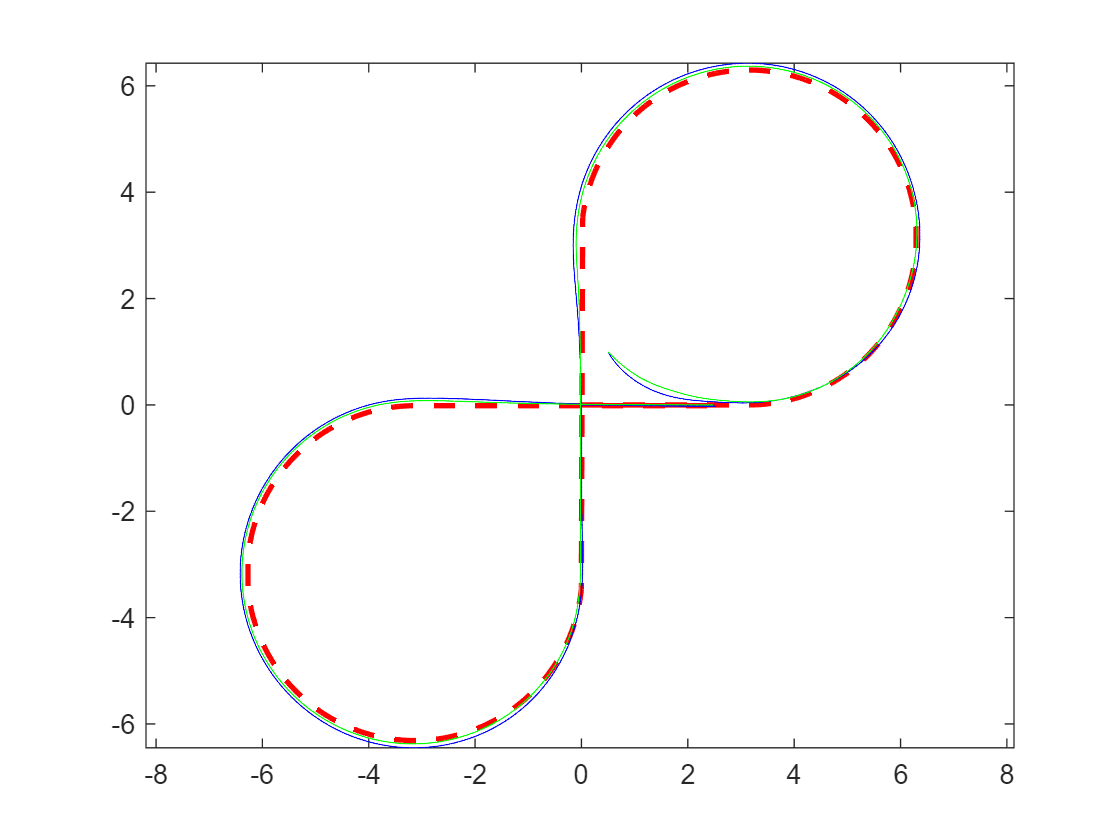

figure(1)
plot(q_d(1,:),q_d(2,:),'r--','LineWidth',2);
hold on
plot(q_HMPC(1,:),q_HMPC(2,:),'b');
hold on
plot(q_GPMPC(1,:),q_GPMPC(2,:),'g');
axis equal


% figure(2)
% subplot(3,1,1)
% plot(T,q_dot_GPFSF(4,:)-new_a_b_new(1,:),'r.','MarkerSize',10,'MarkerIndices',1:22:N);
% hold on
% plot(T,g_function_GPFSF(1,:),'green-','linewidth',1.2);
% grid on
% 
% subplot(3,1,2)
% plot(T,q_dot_GPFSF(5,:)-new_a_b_new(2,:),'r.','MarkerSize',10,'MarkerIndices',1:22:N);
% hold on
% plot(T,g_function_GPFSF(2,:),'green-','linewidth',1.2);
% grid on
% 
% subplot(3,1,3)
% plot(T,q_dot_GPFSF(6,:)-new_a_b_new(3,:),'r.','MarkerSize',10,'MarkerIndices',1:22:N);
% hold on
% plot(T,g_function_GPFSF(3,:),'green-','linewidth',1.2);
% grid on
